# Explore the Phase plots of **General** and **Mechanical systems**

Let's explore the influence that POLES and ZEROS have on the Magnitude and PHASE of the transfer Functions of Dynamic systems

`Bradley Horton: bhorton@mathworks.com`

Clear the workspace

clear

## General:    A real pole:

- 
$$H\left(s\right)\;\;=\;\frac{1}{1\;+\;\;\frac{s}{5}}$$


H = tf( [ 1], [1/5 1] )


H =
 
      1
  ---------
  0.2 s + 1
 
Continuous-time transfer function.


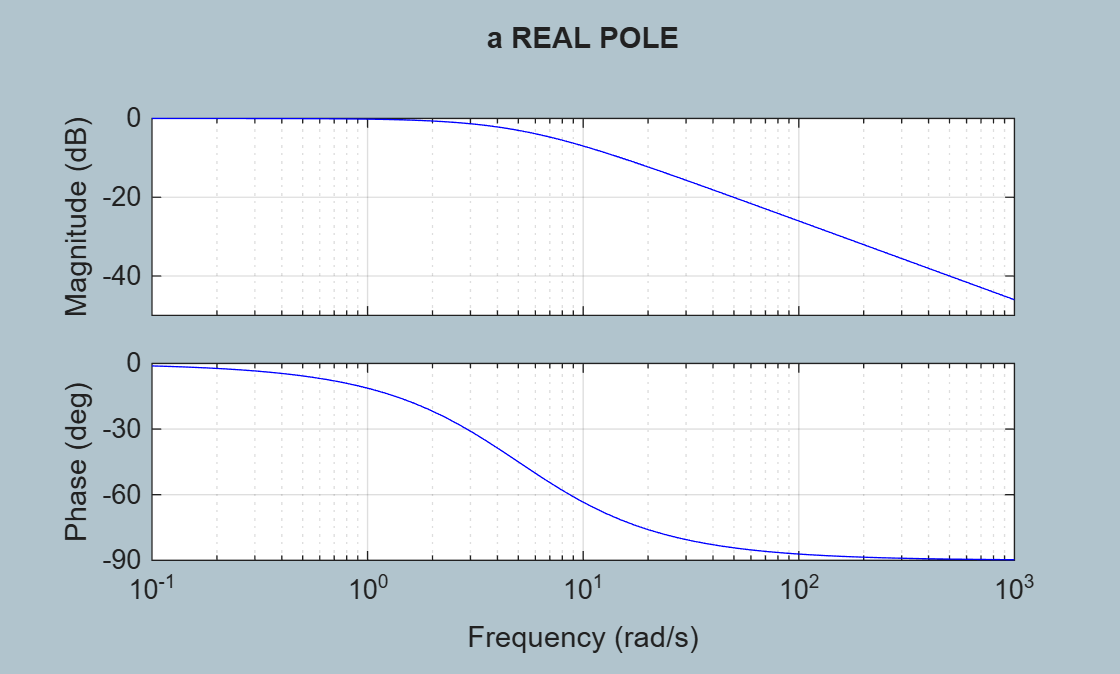


figure;
    bodeplot(H, "b", {0.1, 1000});
        grid on
        title("a REAL POLE")

**NOTE:**

- corner frequency is $\omega_0 =5$

- after the corner frequency we **attenuate** by ***20 dB per decade***

## General:    A real zero:

- 
$$H\left(s\right)\;\;=\;\;1\;\;+\;\;\frac{s}{30}$$


H = tf( [(1/30) 1], [1] )


H =
 
  0.03333 s + 1
 
Continuous-time transfer function.


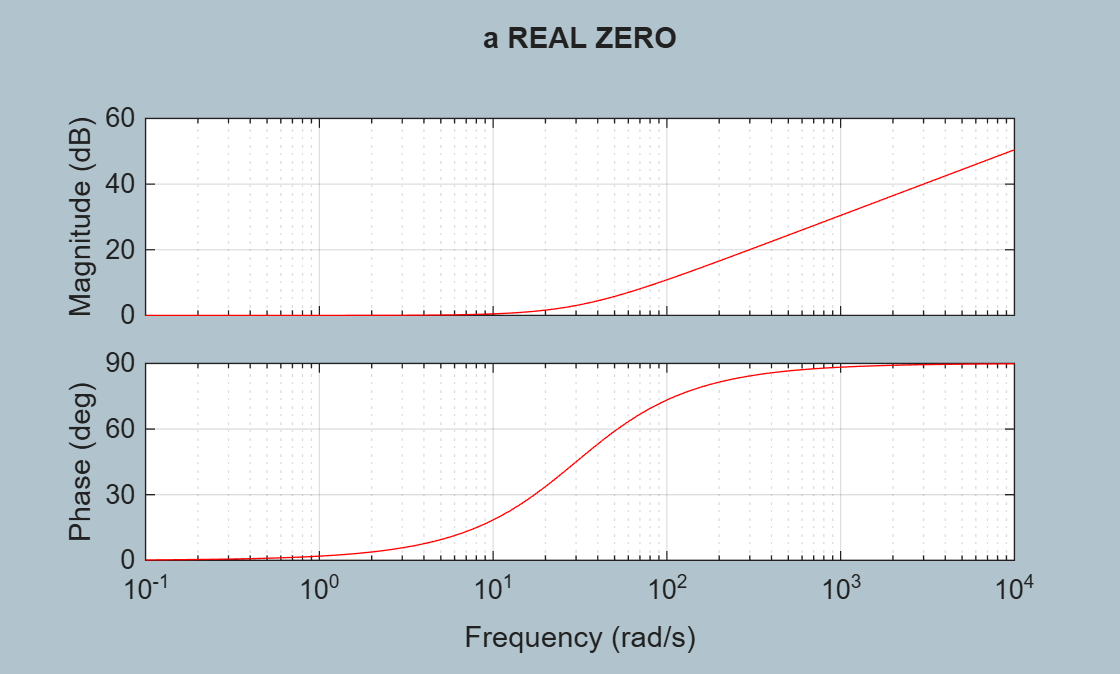


figure;
    bodeplot(H, "r", {0.1, 1e4});
        grid on
        title("a REAL ZERO")

**NOTE:**

- corner frequency is $\omega_0 =30$

- after the corner frequency we **amplify** by ***20 dB per decade***

## General:    Two real poles:

- 
$$H\left(s\right)\;\;=\left(\frac{1}{1\;+\;\;\frac{s}{5}}\right)\ldotp \left(\frac{1}{1\;+\;\;\frac{s}{100}}\right)$$


H1 = tf( [ 1], [1/5, 1]   ) 


H1 =
 
      1
  ---------
  0.2 s + 1
 
Continuous-time transfer function.


H2 = tf( [ 1], [1/100, 1] ) 


H2 =
 
      1
  ----------
  0.01 s + 1
 
Continuous-time transfer function.


H  = H1 * H2


H =
 
            1
  ----------------------
  0.002 s^2 + 0.21 s + 1
 
Continuous-time transfer function.


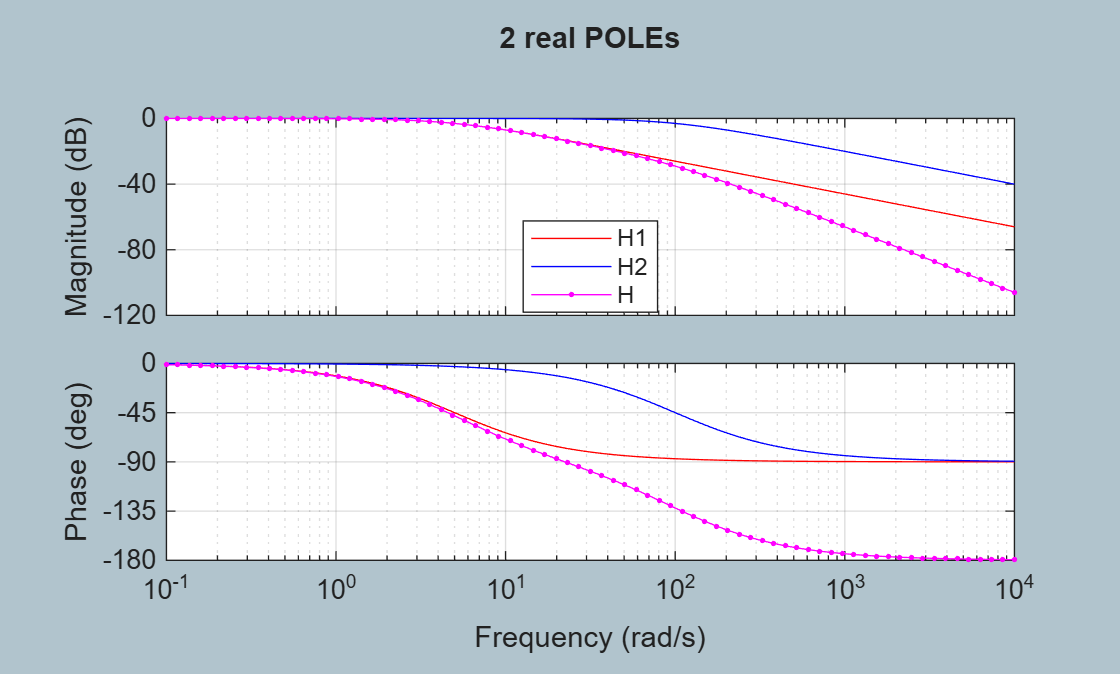


figure;
    bodeplot(H1, "r", H2, "b", H, "-m.", {0.1, 1e4});
        grid on
        title("2 real POLEs")
        legend({"H1","H2","H"}, "Location", "best")

## General:    A complex conjugate pair of POLES:

- 
$$H\left(s\right)\;\;=\;\frac{1}{s^2 \;\;+\;0\ldotp 1\ldotp s\;\;+5^2 }$$


H = tf( [ 1], [1, 2*0.01*5, 25]   ) 


H =
 
         1
  ----------------
  s^2 + 0.1 s + 25
 
Continuous-time transfer function.


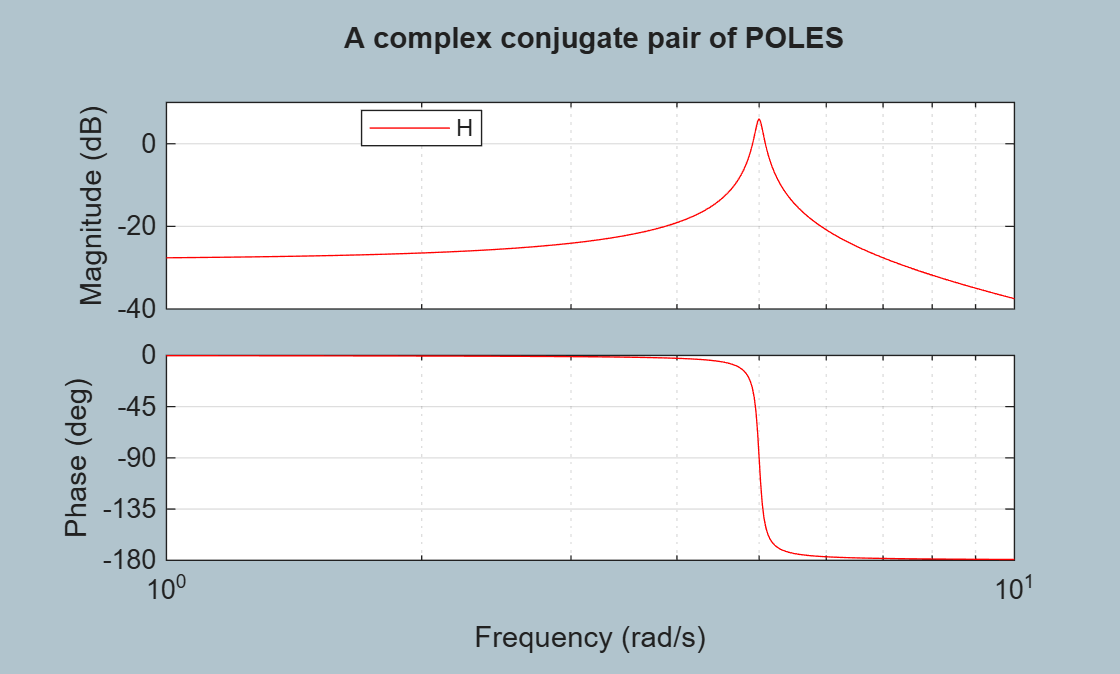


figure;
    bodeplot(H, "r", {1, 10});
        grid on
        title(" A complex conjugate pair of POLES")
        legend({"H"}, "Location", "best")

## General:    A complex conjugate pair of ZEROS:

- 
$$H\left(s\right)\;\;=s^2 \;\;+\;0\ldotp 1\ldotp s\;\;+5^2$$


H = tf( [1, 2*0.01*5, 25], 1   ) 


H =
 
  s^2 + 0.1 s + 25
 
Continuous-time transfer function.


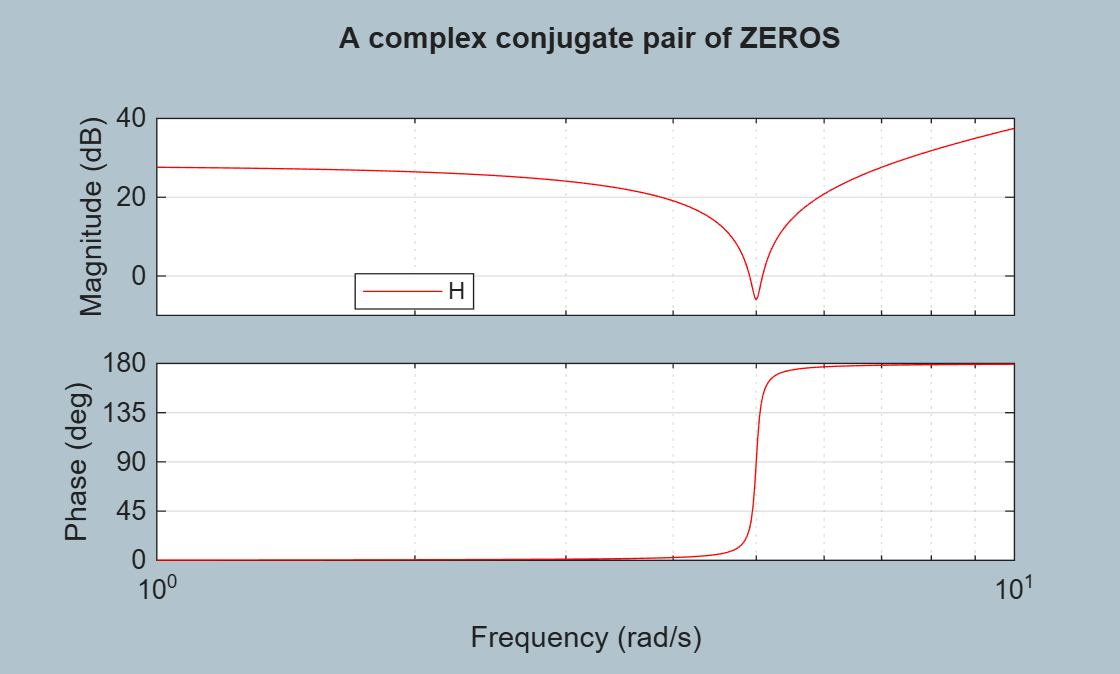


figure;
    bodeplot(H, "r", {1, 10});
        grid on
        title(" A complex conjugate pair of ZEROS")
        legend({"H"}, "Location", "best")

## General:    A real pole AND a real zero - LEAD Compensator

- $G_{\mathrm{LEAD}} \;\;=\;\;\frac{\frac{s}{\left(\frac{1}{T}\right)}\;+\;1}{\frac{s}{\left(\;\frac{1}{\alpha \ldotp T}\;\right)}\;+\;1}$    where   $\left(0<\alpha \;<1\;\right)$

So we have:

- ZERO =      $-\left(\frac{1}{T}\right)$

- POLE = $\;\;-\left(\frac{1}{\alpha \ldotp T}\right)$

T  = 1;
a  = 0.01;  assert(a < 1);
Kc = 1000;

G_lead = tf([ 1/(1/T), 1], [ 1/(1/(a*T)), 1])


G_lead =
 
    s + 1
  ----------
  0.01 s + 1
 
Continuous-time transfer function.



[   zero(G_lead);
    pole(G_lead)   ]

ans =     -1
  -100


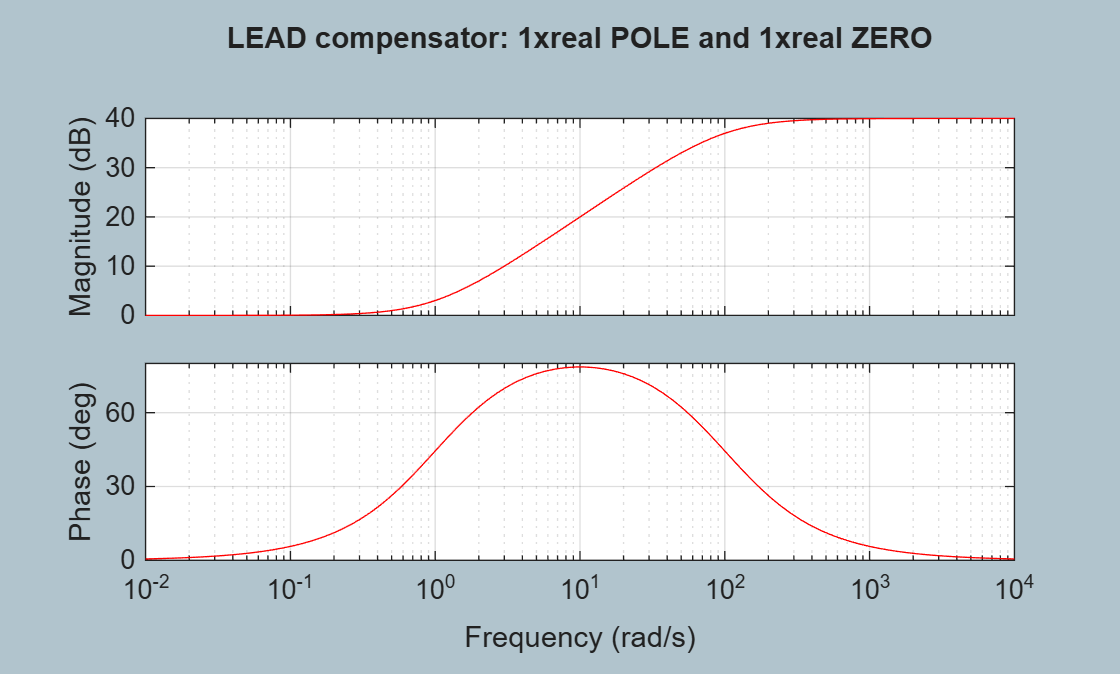


figure;
    bodeplot(G_lead, "r",  {1e-2, 1e4});
        grid on
        title("LEAD compensator: 1xreal POLE and 1xreal ZERO")

## General:    A real pole AND a real zero - LAG Compensator

- $G_{\mathrm{LAG}} \;\;=\;\;\frac{\frac{s}{\left(\frac{1}{T}\right)}\;+\;1}{\frac{s}{\left(\;\frac{1}{\beta \ldotp T}\;\right)}\;+\;1}$    where   $\beta >1$

T  = 0.001;
B  = 10;  assert(B > 1);

G_lag = tf([ 1/(1/T), 1], [ 1/(1/(B*T)), 1])


G_lag =
 
  0.001 s + 1
  -----------
  0.01 s + 1
 
Continuous-time transfer function.


Echo the the ZERO and POLE of the LAG Compensator

[   zero(G_lag);
    pole(G_lag)   ]       

ans =        -1000
        -100


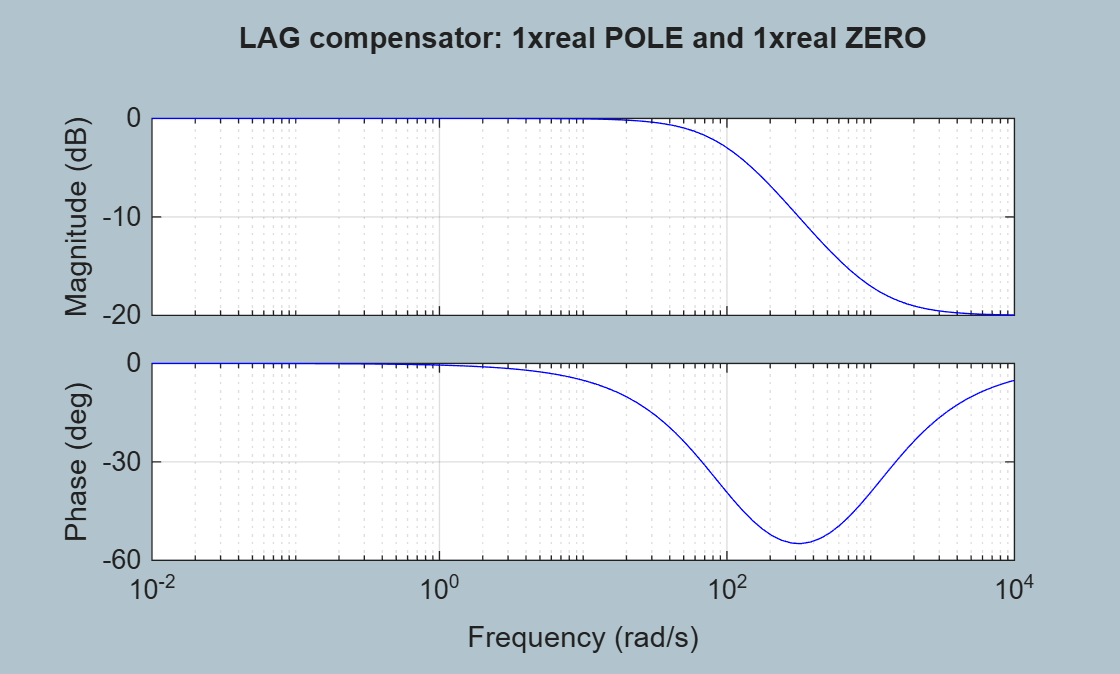


figure;
    bodeplot(G_lag, "b",  {1e-2, 1e4});
        grid on
        title("LAG compensator: 1xreal POLE and 1xreal ZERO")

## General:    A LEAD-LAG Compensator

recall our LEAD and LAG filters:

- $G_{\mathrm{LEAD}} \;\;=\;\;\frac{\frac{s}{\left(\frac{1}{T}\right)}\;+\;1}{\frac{s}{\left(\;\frac{1}{\alpha \ldotp T}\;\right)}\;+\;1}$    where   $\left(0<\alpha \;<1\;\right)$

- $G_{\mathrm{LAG}} \;\;=\;\;\frac{\frac{s}{\left(\frac{1}{T}\right)}\;+\;1}{\frac{s}{\left(\;\frac{1}{\beta \ldotp T}\;\right)}\;+\;1}$    where   $\beta >1$

So our Lead-Lag filter is:

- 
$$G\left(s\right)\;=G_{\mathrm{LAG}} \left(s\right)\;\ldotp G_{\mathrm{LEAD}} \left(s\right)$$


T  = 1;
B  = 10;  assert(B > 1);
G_lag = tf([ 1/(1/T), 1], [ 1/(1/(B*T)), 1])    


G_lag =
 
   s + 1
  --------
  10 s + 1
 
Continuous-time transfer function.


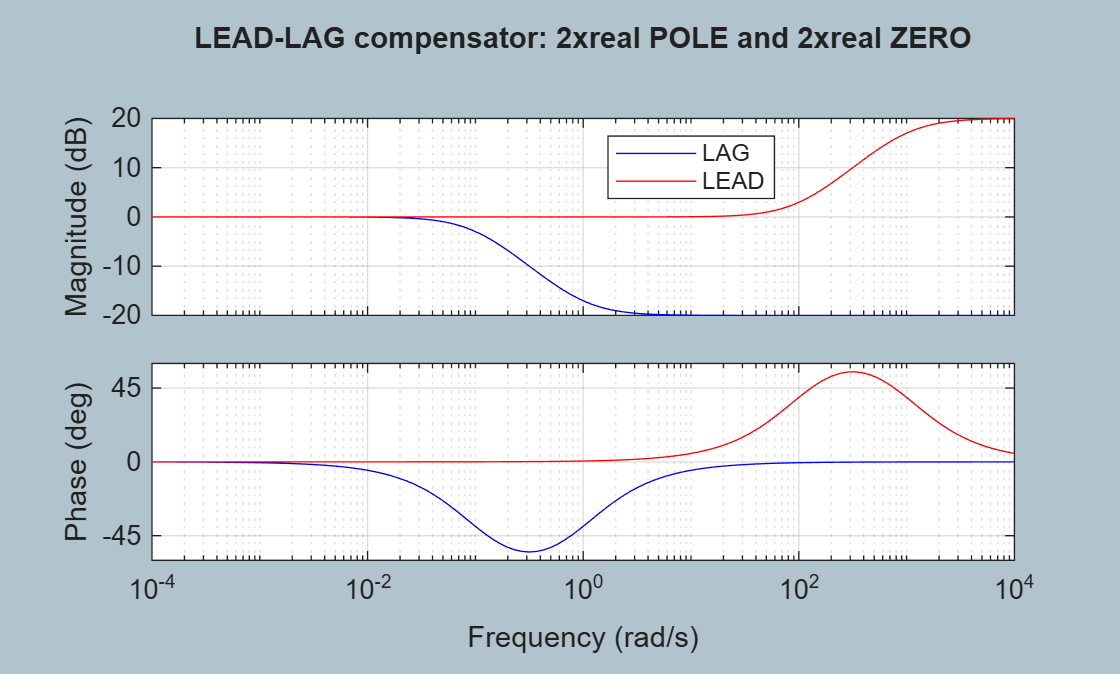



T  = 0.01;
a  = 0.1;  assert(a < 1);

G_lead = tf([ 1/(1/T), 1], [ 1/(1/(a*T)), 1]);

G = G_lag * G_lead;

figure;
    bodeplot(G_lag, "b",  G_lead, "r",  {1e-4, 1e4});
        grid on
        legend({"LAG","LEAD"},'Location', 'best')        
        title("LEAD-LAG compensator: 2xreal POLE and 2xreal ZERO")

## General:    2 conj pair POLES and 1 conj pair ZEROS


$$H\left(s\right)\;\;=\left(\frac{1}{s^2 \;\;+\;2\ldotp \left(0\ldotp 01\right)\ldotp 5\;\ldotp \;s\;\;+5^2 }\right)\ldotp \left(\frac{1}{s^2 \;\;+2\ldotp \left(0\ldotp 01\right)\ldotp 50\;\;+{50}^2 }\right)\ldotp \left(s^2 \;\;+\;2\ldotp \left(0\ldotp 01\right)\ldotp 25\;\ldotp \;s\;\;+{25}^2 \right)$$


H = tf(  [1], [1, (2*0.01*5),   (5^2)] ) * ...
    tf(  [1], [1, (2*0.01*50), (50^2)] ) * ... 
    tf(  [1, (2*0.01*10), (10^2)], [1] ) 


H =
 
             s^2 + 0.2 s + 100
  ----------------------------------------
  s^4 + 1.1 s^3 + 2525 s^2 + 275 s + 62500
 
Continuous-time transfer function.


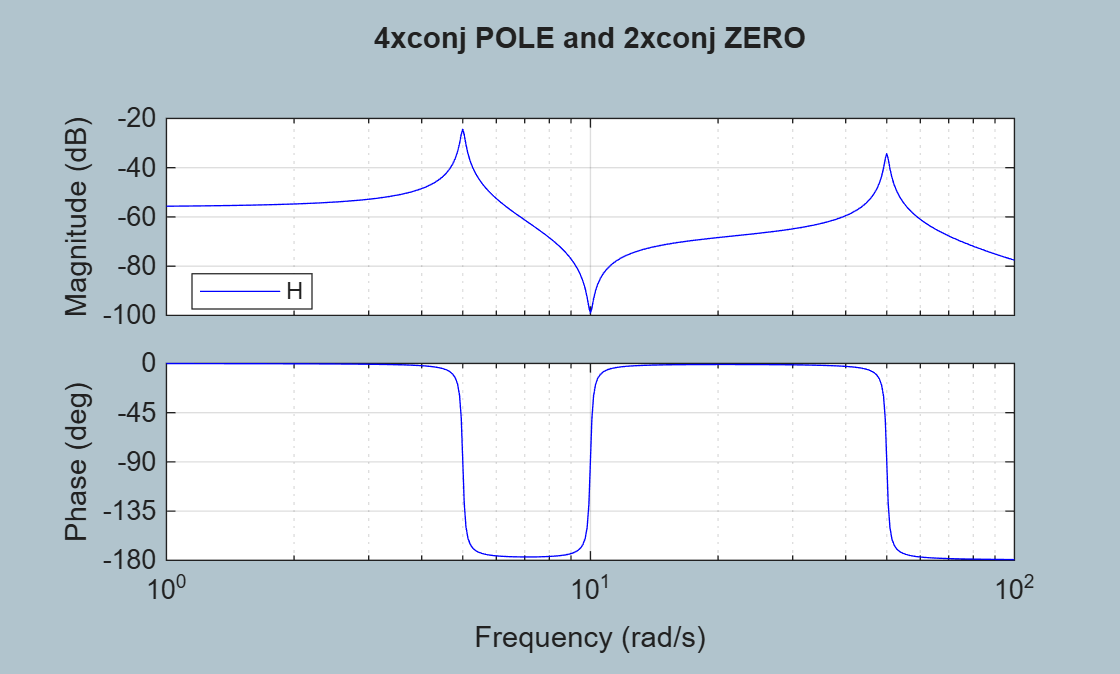


figure;
    bodeplot(H, "b",  {1, 1e2});
        grid on
        legend({"H"},'Location', 'best')        
        title("4xconj POLE and 2xconj ZERO")

## Mechanical:    a 1-dof system

Consider the case of a single degree of freedom system:

- 
$$m\ldotp \ddot{x} \;\;\;+\;c\ldotp \dot{x} \;\;+\;k\ldotp x\;\;=\;\;f$$


The **Transfer function **representation of this system is:

- 
$$H\left(s\right)\;\;=\;\;\frac{1}{m\ldotp s^2 \;\;+\;c\ldotp s\;\;+\;k}\;\;\;=\;\;\;\;\frac{\frac{1}{m}}{s^2 \;\;\;+\;\;\;2\ldotp \zeta \ldotp \omega_n \ldotp s\;\;\;\;+\;\;\;\omega_n^2 }\;$$


Let's assume $m=1$, so our 1-dof Transfer Function is:

- 
$$H\left(s\right)\;\;=\;\;\frac{1}{s^2 \;\;+\;\;\;2\ldotp \zeta \ldotp \omega_n \ldotp s\;\;\;+\;\;\;\omega_n^2 }$$


This transfer function has POLES at:

- 
$$\lambda \;\;=\;\;-\zeta \ldotp {\omega_n \;\;+\;\;j\ldotp \omega_n \ldotp \sqrt{1-\zeta^2 }}_{\;}$$


- 
$$\bar{\lambda} \;\;=\;\;-\zeta \ldotp {\omega_n \;\;-\;\;j\ldotp \omega_n \ldotp \sqrt{1-\zeta^2 }}_{\;}$$


dr = 0.01;
wn = 5;
fn = wn/(2*pi);

THE_POLES = [(-dr*wn + 1i*wn*sqrt(1 - dr^2));
             (-dr*wn - 1i*wn*sqrt(1 - dr^2)) ]

THE_POLES =   -0.0500 + 4.9997i
  -0.0500 - 4.9997i


Define the Transfer Function

H_tf_obj = tf(  [1], [1, (2*dr*wn), (wn^2)]     )


H_tf_obj =
 
         1
  ----------------
  s^2 + 0.1 s + 25
 
Continuous-time transfer function.


Plot the Frequency Response 

- we'll wrap the phase to the range $\mp {180}^o$

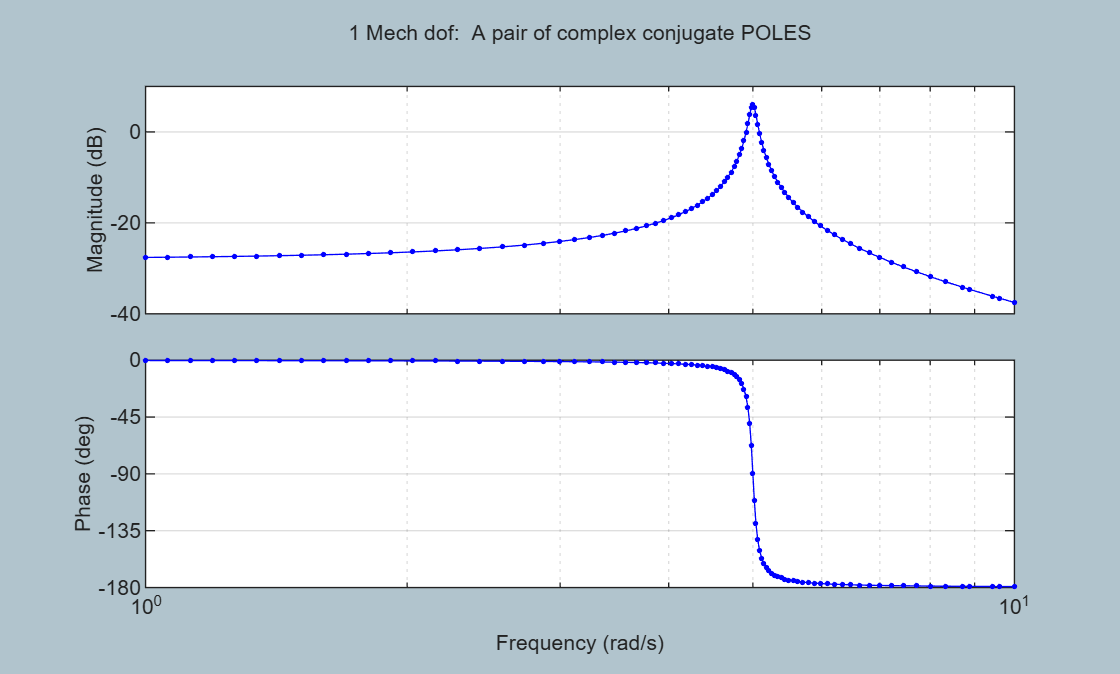

my_plot_opts = bodeoptions;
my_plot_opts.PhaseWrapping = "on";

figure;
    bodeplot( H_tf_obj, "-b.", {1, 10}, my_plot_opts);
        grid on
        title("1 Mech dof:  A pair of complex conjugate POLES")

## Mechanical:    a 2-dof system

Consider the following undamped 2-dof system:

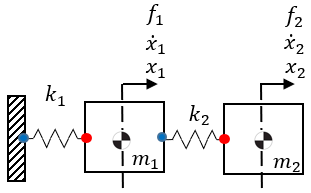

The equations of motion for this system are:

- $\pmatrix{
m_1 & 0 \cr
0 & m_2 \cr
}$$. \pmatrix{
\ddot{x}_1 \cr
\ddot{x}_2 \cr
}$  +  $\pmatrix{
(k_1 + k_2) & -k_2 \cr
-k_2 & k_2 \cr
}$$. \pmatrix{
{x}_1 \cr
{x}_2 \cr
}$= $\pmatrix{
{f}_1 \cr
{f}_2 \cr
}$

Which we can write in matrix form as:   

- $M \ddot{x}  +   Kx = f$   where   $x \in R^{n\times1}$    and   $f \in R^{n\times1}$

And let's assume that we have a damping matrix C defined as:

- 
$$C=\gamma \ldotp K$$


So the Equations of motion for the damped system is

-  
$$M \ddot{x}  +   C \dot{x}  +  Kx = f$$
   

Which can also be expressed as the $1^{\mathrm{st}}$ order system :

- $\pmatrix{
\ddot{x} \cr
\dot{x} \cr
}$ = $\pmatrix{
-M^{-1}C & -M^{-1}K \cr
I_{n \times n} & 0_{n \times n} \cr
}$$. \pmatrix{
\dot{x} \cr
x \cr
}$  +  $\pmatrix{
M^{-1} \cr
0_{n \times n} \cr
}.f$

Which has the form:

- $\dot{z} = A . z + B.u$    where:  $Z =  \pmatrix{
\dot{x} \cr
x \cr
} \in R^{2n \times 1}$   and    $B = \pmatrix{
M^{-1} \cr
0_{n \times n} \cr
}$    and    $A = \pmatrix{
-M^{-1}{C} & -M^{-1}{K}\cr
I_{n \times n} & 0_{n \times n} \cr
}$

And let's just measure the displacements

- $y=G\ldotp z\;+\;D\ldotp u$     where    $G=\;\left\lbrack \begin{array}{cc}
0_{n\times n}  & I_{n\times n} 
\end{array}\right\rbrack$    and  $D=0_{n\times n}$

So define the Mechanical system

k1 = 1e4;  % (N/m)
m1 = 1e2;  % (kg)
k2 = 1e3;  % (N/m)
m2 = 5;    % (kg)

M = [m1, 0; 
      0, m2 ];
K = [(k1+k2), (-k2);
       (-k2),  (k2)];
C = 0.001*K;
%C = 0.01*K;

Define the State Space system

A = [-inv(M)*C, -inv(M)*K;  eye(2), zeros(2)];
B = [inv(M);zeros(2)];
G = [zeros(2), eye(2)];
D = zeros(2);

% H_ss = ss(A,B,G,D,0,"Outputname",{"x1","x2"},"InputName",{"f1","f2"});  % oohh comeon R2025 ???
H_ss = ss(A,B,G,D,0,"Outputname",{'x1','x2'},"InputName",{'f1','f2'});

What are the system POLES:

damp(H_ss)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.58e-02 + 9.57e+00i     4.78e-03       9.57e+00         2.18e+01    
 -4.58e-02 - 9.57e+00i     4.78e-03       9.57e+00         2.18e+01    
 -1.09e-01 + 1.48e+01i     7.39e-03       1.48e+01         9.16e+00    
 -1.09e-01 - 1.48e+01i     7.39e-03       1.48e+01         9.16e+00    


### Plot the Frequency Response  (NO Phase wrapping)

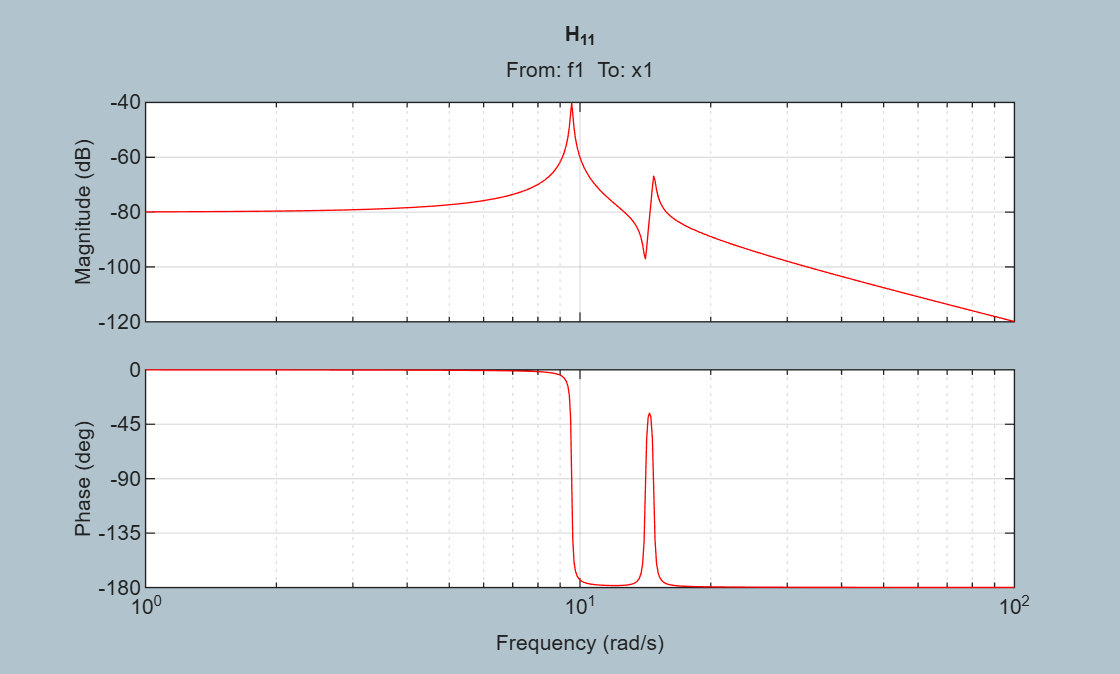

my_plot_opts = bodeoptions;
my_plot_opts.PhaseWrapping = "off";

figure;  bodeplot(H_ss(1,1),'-r', {1, 1e2}, my_plot_opts); grid on; title("H_{11}", "FontWeight","bold");

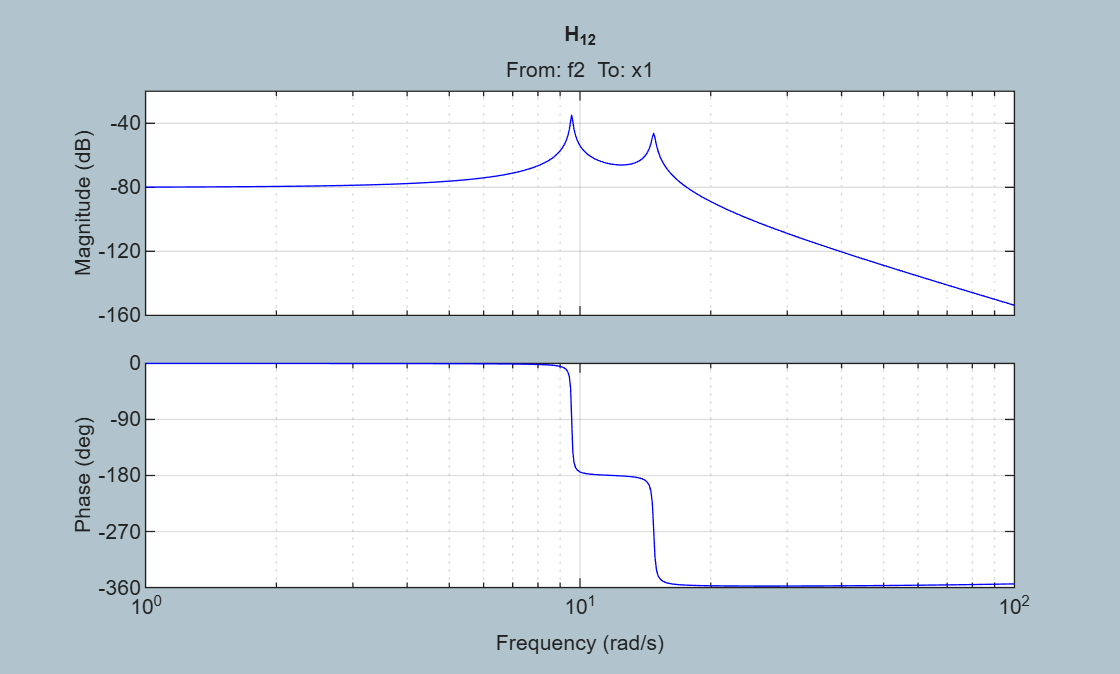

figure;  bodeplot(H_ss(1,2),'-b', {1, 1e2}, my_plot_opts); grid on; title("H_{12}", "FontWeight","bold");

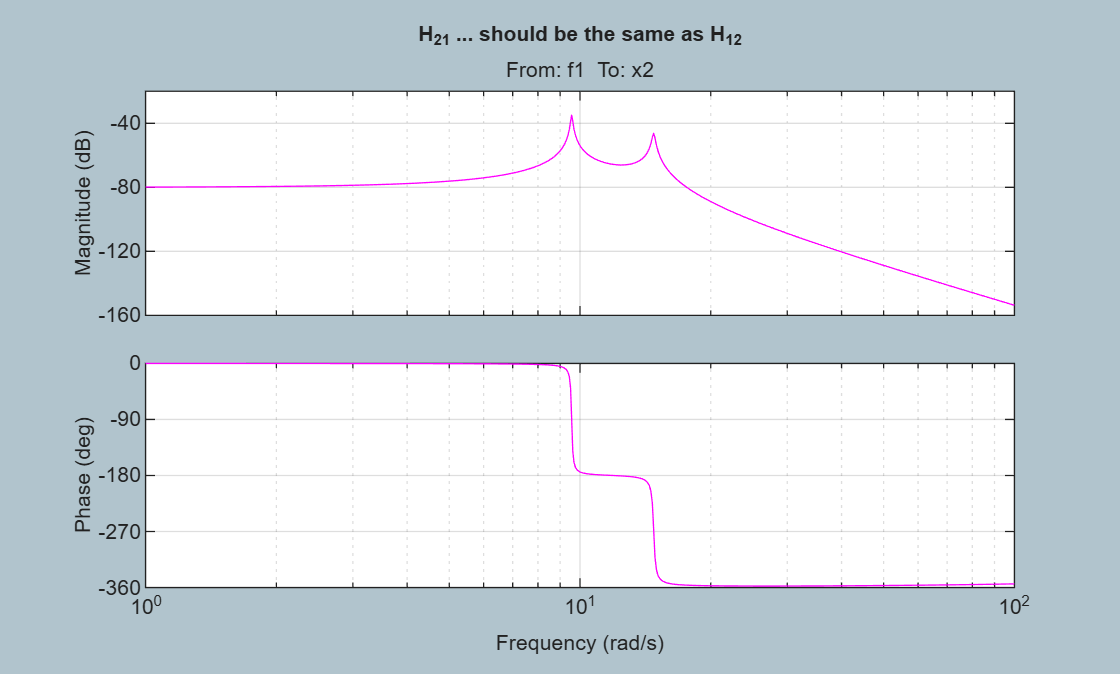

figure;  bodeplot(H_ss(2,1),'-m', {1, 1e2}, my_plot_opts); grid on; title("H_{21} ... should be the same as H_{12}", "FontWeight","bold");

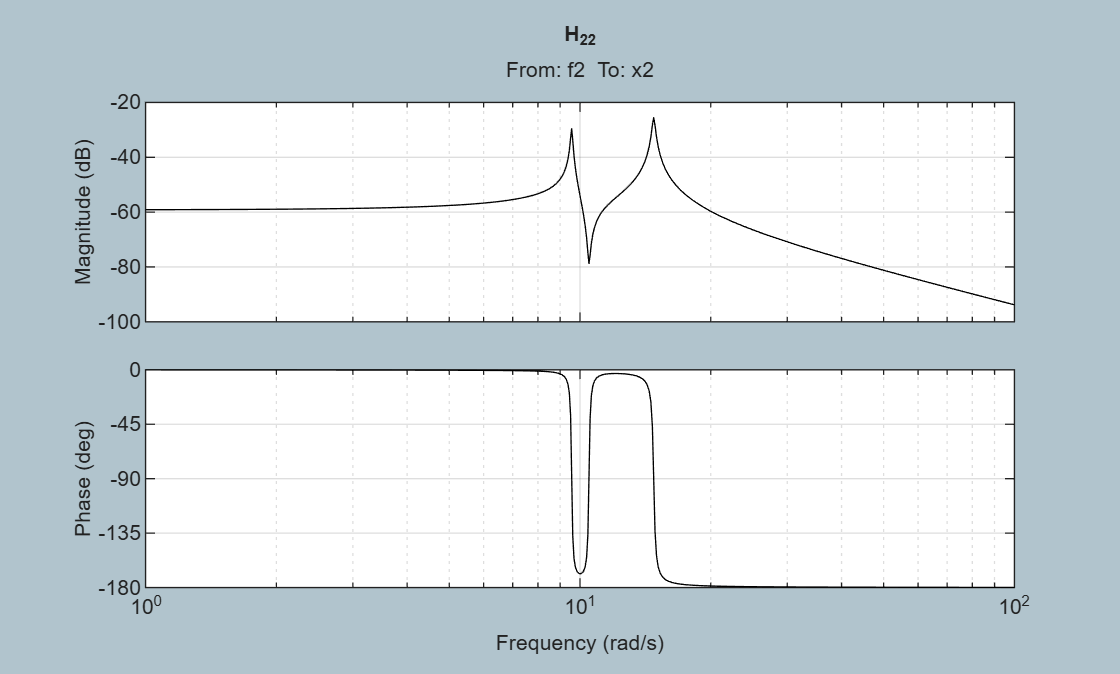

figure;  bodeplot(H_ss(2,2),'-k', {1, 1e2}, my_plot_opts); grid on; title("H_{22}", "FontWeight","bold");

### Some observations:   **Direct Transfer functions** $H_{\mathrm{kk}}$

The **Direct Transfer functions** $H_{\mathrm{kk}}$ have has a phase plot in the range  $\left\lbrack -180,\;0\right\rbrack$

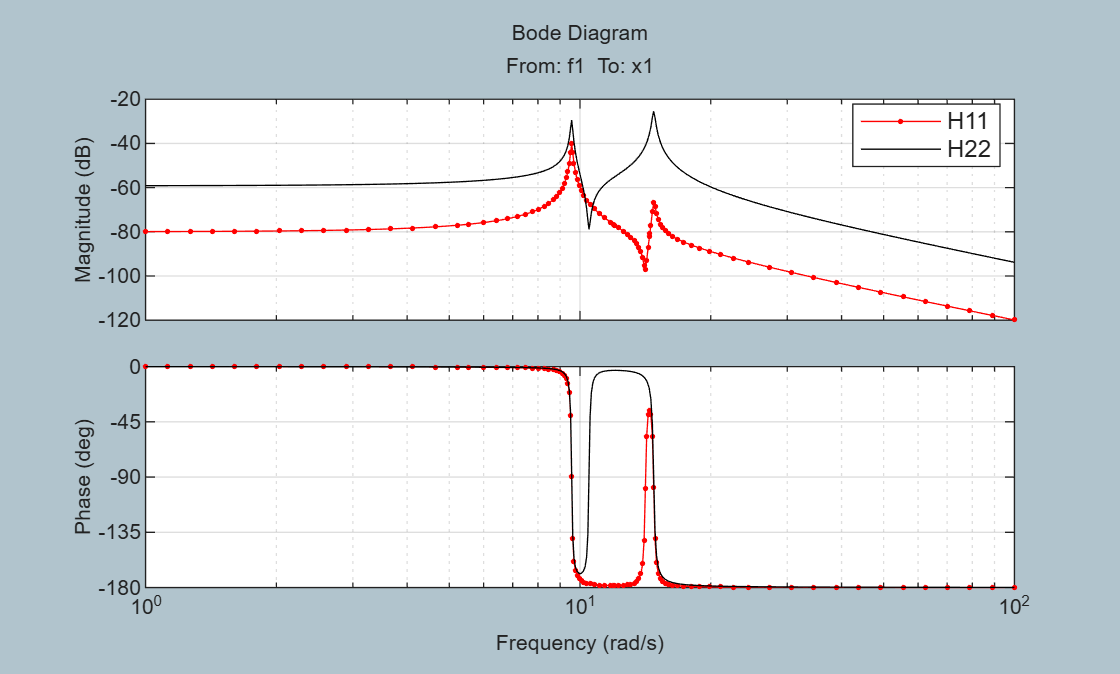

figure;  
    bodeplot(H_ss(1,1),'-r.', H_ss(2,2),'-k', {1, 1e2}, my_plot_opts); grid on
        legend({"H11", "H22"}, "Location","best")

The **Direct Transfer functions** $H_{\mathrm{kk}}$ have complex POLES and ZEROS.  And we can see this also by displaying the Direct transfer functions in Zero-Pole-Gain form:

#### For H_22:

fprintf("\n ... H_22 -----> ");


 ... H_22 -----> 

zpk(H_ss(2,2))


ans =
 
  From input "f2" to output "x2":
              0.2 (s^2 + 0.11s + 110)
  ------------------------------------------------
  (s^2 + 0.09156s + 91.56) (s^2 + 0.2184s + 218.4)
 
Continuous-time zero/pole/gain model.


%[z,p,k] = zpkdata(H_ss(2,2), 'v')

#### For H_11:

fprintf("\n ... H_11 -----> ");


 ... H_11 -----> 

zpk(H_ss(1,1))


ans =
 
  From input "f1" to output "x1":
              0.01 (s^2 + 0.2s + 200)
  ------------------------------------------------
  (s^2 + 0.09156s + 91.56) (s^2 + 0.2184s + 218.4)
 
Continuous-time zero/pole/gain model.


%[z,p,k] = zpkdata(H_ss(1,1), 'v')

#### Explore H_11 more:  Individual Phase and Mag contributions

Let's look at the individual pieces of $H_{11}$ 

[z,p,k] = zpkdata(H_ss(1,1), 'v')

z =   -0.1000 +14.1418i
  -0.1000 -14.1418i


p =   -0.0458 + 9.5684i
  -0.0458 - 9.5684i
  -0.1092 +14.7794i
  -0.1092 -14.7794i


k = 0.0100

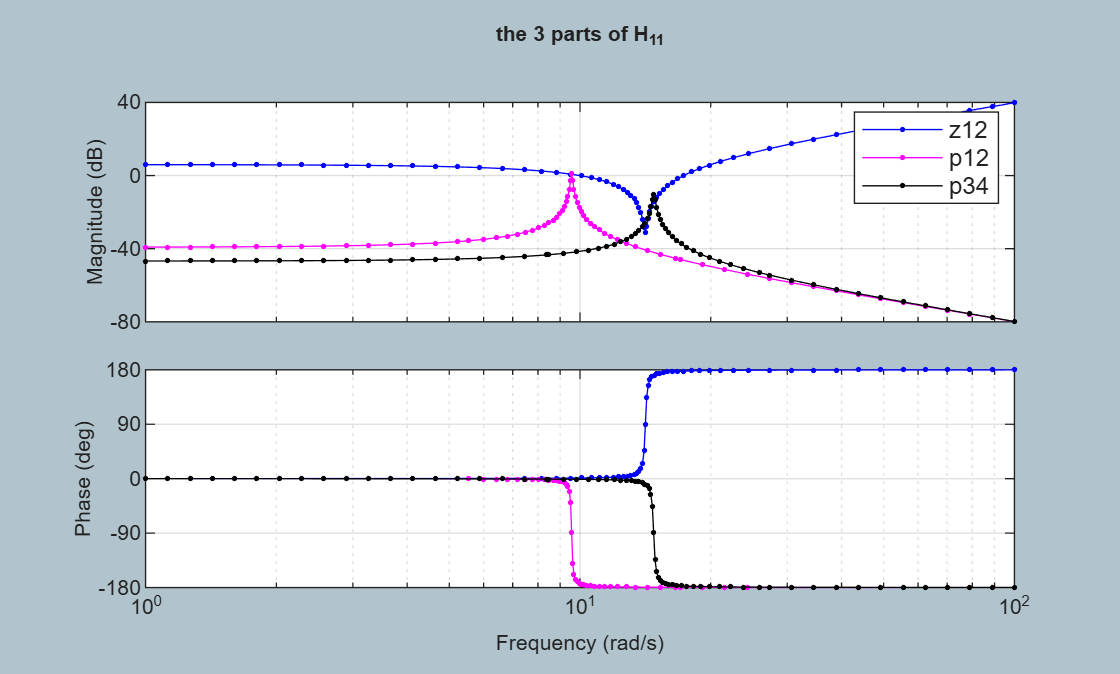


part_1 = zpk(z(1:2), [], k(1));
part_2 = zpk([], [p(1:2)], 1);
part_3 = zpk([], [p(3:4)], 1);

figure;  
    bodeplot(part_1,'-b.', part_2,'-m.', part_3,'-k.', {1, 1e2}, my_plot_opts); grid on
        legend({"z12", "p12", "p34"}, "Location","best")
        title("the 3 parts of H_{11}", "FontWeight","bold")

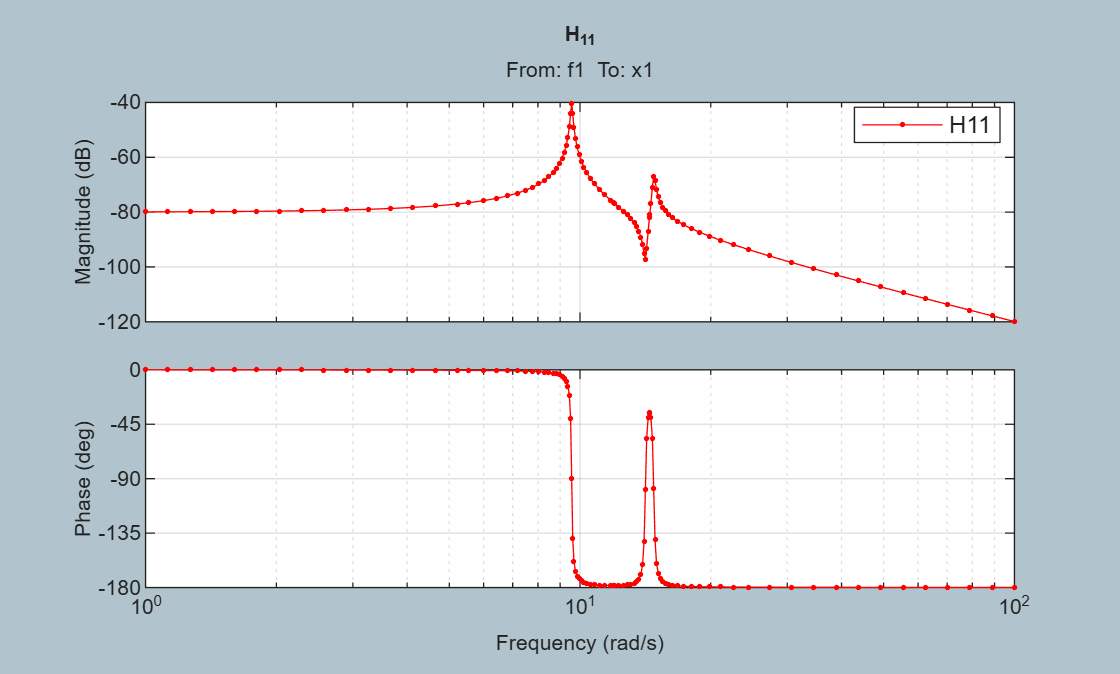


figure;  
    bodeplot(H_ss(1,1),'-r.', {1, 1e2}, my_plot_opts); grid on
        legend({"H11"}, "Location","best")
        title("H_{11}", "FontWeight","bold")

### Some observations:   **Cross Transfer functions H_mk**

The **Cross Transfer functions** $H_{\mathrm{mk}}$ have has a phase plot in the range  $\left\lbrack -360,0\right\rbrack$

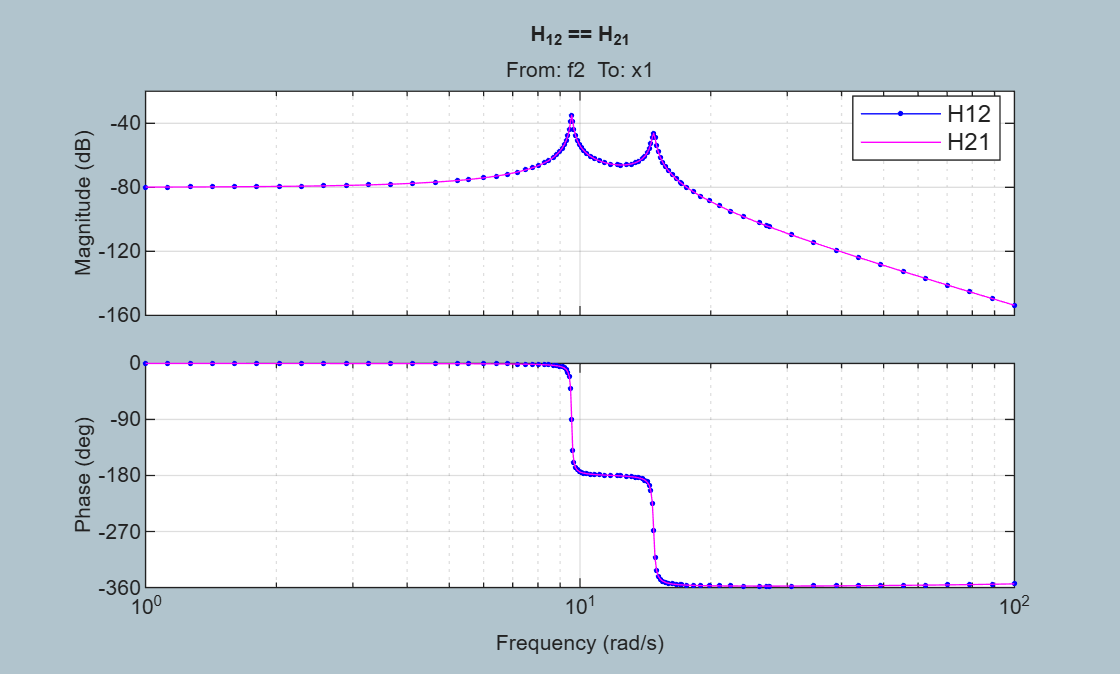

figure;  
    bodeplot(H_ss(1,2),'-b.', H_ss(2,1),'-m', {1, 1e2}, my_plot_opts); grid on
        legend({"H12", "H21"}, "Location","best")
        title("H_{12} == H_{21}", "FontWeight","bold")

The **Cross Transfer functions** $H_{\mathrm{mk}}$ has a real ZERO. And we can see this also by displaying the Direct transfer functions in Zero-Pole-Gain form:

#### For H_12 (==H_21):

fprintf("\n ... H_12 -----> ");


 ... H_12 -----> 

zpk(H_ss(1,2))


ans =
 
  From input "f2" to output "x1":
                   0.002 (s+1000)
  ------------------------------------------------
  (s^2 + 0.09156s + 91.56) (s^2 + 0.2184s + 218.4)
 
Continuous-time zero/pole/gain model.


#### Explore H_12 more:  Individual Phase and Mag contributions

Let's look at the individual pieces of $H_{12}$ 

[z,p,k] = zpkdata(H_ss(1,2), 'v')

z = -1.0000e+03

p =   -0.0458 + 9.5684i
  -0.0458 - 9.5684i
  -0.1092 +14.7794i
  -0.1092 -14.7794i


k = 0.0020

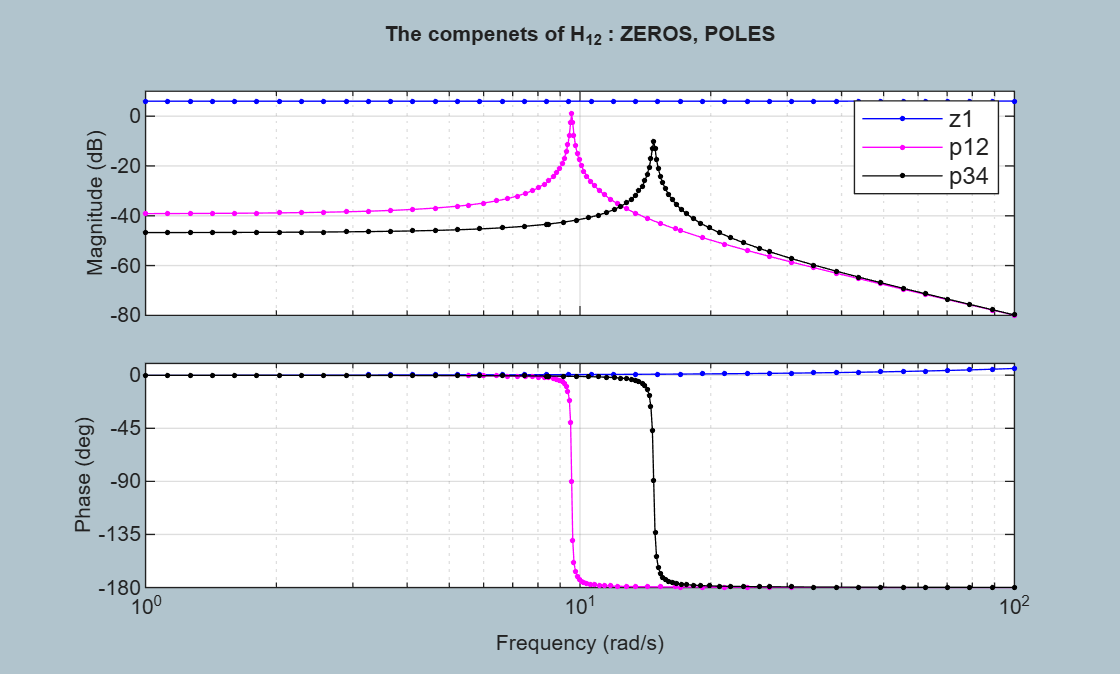


part_1 = zpk(z(1), [], k(1));
part_2 = zpk([], [p(1:2)], 1);
part_3 = zpk([], [p(3:4)], 1);

figure;  
    bodeplot(part_1,'-b.', part_2,'-m.', part_3,'-k.', {1, 1e2}, my_plot_opts); grid on
        legend({"z1", "p12", "p34"}, "Location","best")
        title("The compenets of H_{12} : ZEROS, POLES", "FontWeight","bold")

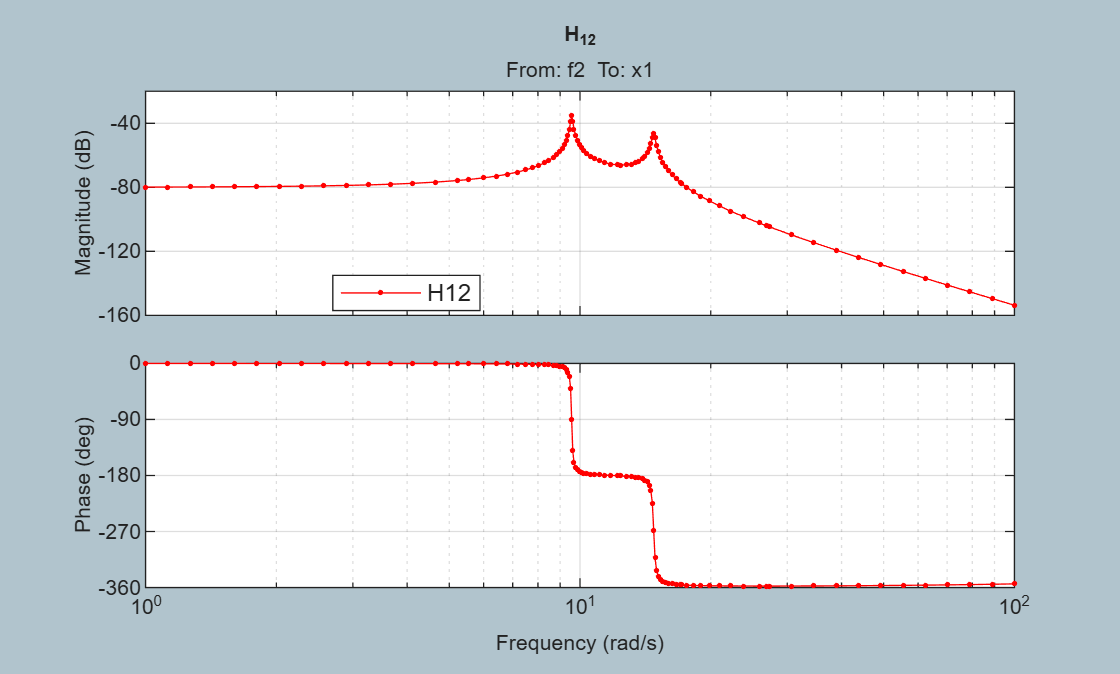


figure;  
    bodeplot(H_ss(1,2),'-r.', {1, 1e2}, my_plot_opts); grid on
        legend({"H12"}, "Location","best")
        title("H_{12}", "FontWeight","bold")        

### Phase Wrapping:

In some bode plots of the phase, you'll see "discontinuities" in the phase plot - this is just a result of wrapping the phase to the range $\left\lbrack -{180}^o \;\;,{180}^o \;\right\rbrack$.

#### Phase wrapping - OFF

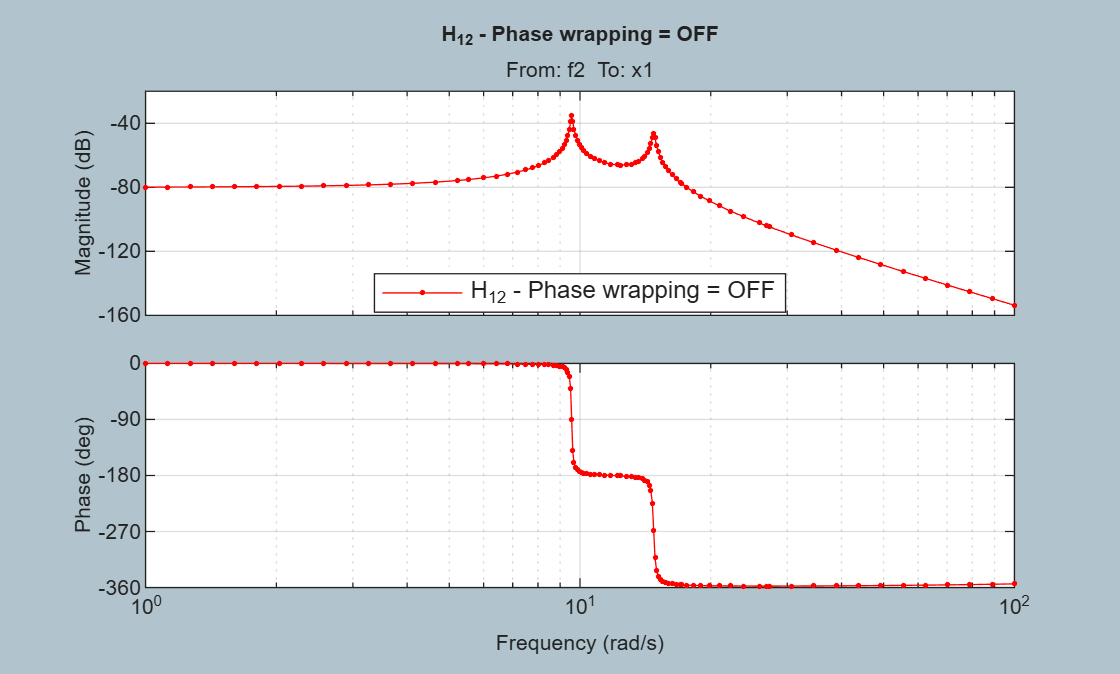

my_plot_opts = bodeoptions;
my_plot_opts.PhaseWrapping = "off";
        
figure;  
    bodeplot(H_ss(1,2),'-r.', {1, 1e2}, my_plot_opts); grid on
        legend({"H_{12} - Phase wrapping = OFF"}, "Location","best")
        title("H_{12} - Phase wrapping = OFF", "FontWeight","bold")

#### Phase wrapping - ON

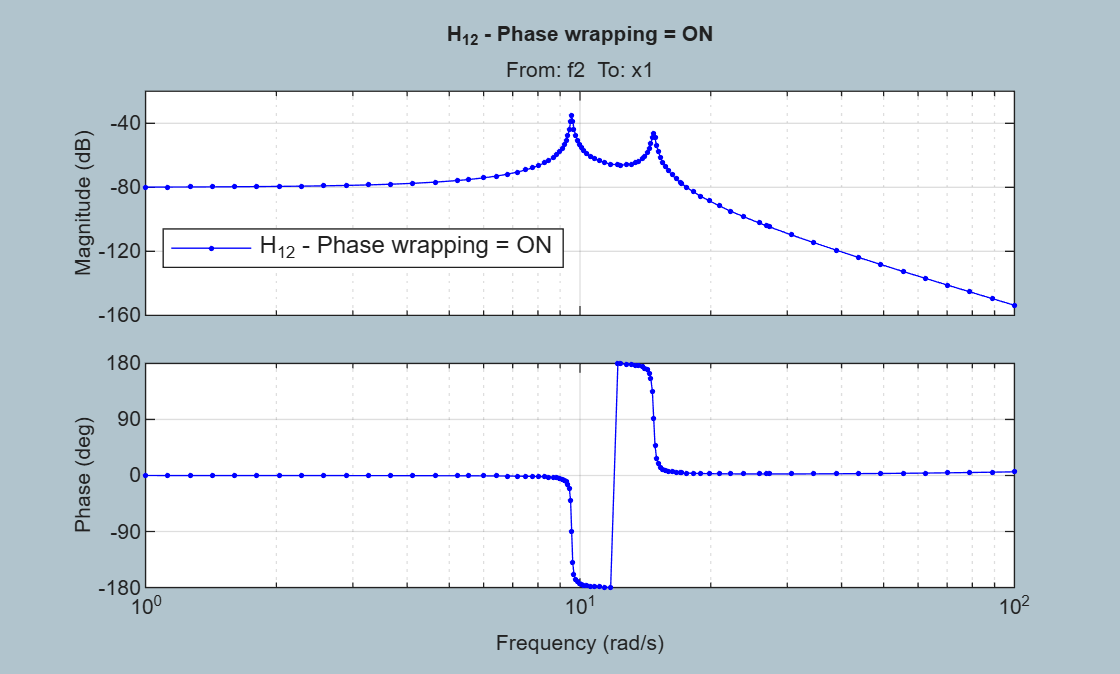

my_plot_opts = bodeoptions;
my_plot_opts.PhaseWrapping = "on";
        
figure;  
    bodeplot(H_ss(1,2),'-b.', {1, 1e2}, my_plot_opts); grid on
        legend({"H_{12} - Phase wrapping = ON"}, "Location","best")
        title("H_{12} - Phase wrapping = ON", "FontWeight","bold")

## Mechanical:    a 7-mode FRF system

Recall the Modal model representation of a Mechanical system:

- ${\left\lbrack H\left(s\right)\right\rbrack }_{\mathrm{yu}} \;\;=\;\sum_{i=1}^P \;\;\frac{{\left\lbrack \phi_i \;\ldotp \phi_i^T \right\rbrack }_{\mathrm{yu}} }{s^2 \;\;+\;2\ldotp \zeta_i \ldotp \omega_{\mathrm{ni}} \ldotp s\;\;+\;\omega_{\mathrm{ni}}^2 }\;\;\;\;\;\;\;\;$where    $A_{\mathrm{yu}}$ denotes **row y ** and **column u**

Let's say that we've done an Experimental Modal Analysis (EMA) on some mechanical structure and we have an ONE experimental FRF - an FRF from a SISO test. From this FRF we've identified 7 modes. 

#### Let's read in this data

- **NOTE:** this looks more difficult than it should be because the MAT file is inside the package folder `+bh_Modal`

tmp_PACK_FOLDER      = bh_Modal.get_package_foldername_str();
tmp_MATFILE_FullPath = fullfile(tmp_PACK_FOLDER, "bh_7modes_datafile.mat");
tmp_MATFILE_FullPath = string(tmp_MATFILE_FullPath);

my_tmp = load(tmp_MATFILE_FullPath, "my_7modes_tab");

my_tmp.my_7modes_tab

ans = 7×3 table
      wn        zeta        imag_R 
    ______    _________    ________

     159.7     0.050312     -0.1675
    443.04     0.028183    0.094447
    856.67     0.011459     0.56458
      1382     0.010179     -0.1737
    1989.2    0.0083069    -0.64864
    2616.9    0.0076103     0.16665
    3128.8    0.0058406     0.28376


#### Convert to Second Order Sections

Now let's convert these modes into their Second Order Sections (sos) according to the Modal modal

for kk=1:height(my_tmp.my_7modes_tab)
    a_row    = my_tmp.my_7modes_tab(kk,:);
    THE_top  = -2*a_row.imag_R*a_row.wn*sqrt(1 - a_row.zeta^2);
    THE_sos  = tf(THE_top,[1, (2*a_row.wn*a_row.zeta), (a_row.wn^2)])

    list_of_sos{kk} = THE_sos;
end


THE_sos =
 
           53.43
  -----------------------
  s^2 + 16.07 s + 2.55e04
 
Continuous-time transfer function.


#### Construct the Transfer Function

And now let's create our TRANSFER FUNCTION 

- 
$${\left\lbrack H\left(s\right)\right\rbrack }_{\mathrm{yu}} \;\;=\;\sum_{i=1}^P \;\;\frac{{\left\lbrack \phi_i \;\ldotp \phi_i^T \right\rbrack }_{\mathrm{yu}} }{s^2 \;\;+\;2\ldotp \zeta_i \ldotp \omega_{\mathrm{ni}} \ldotp s\;\;+\;\omega_{\mathrm{ni}}^2 }\;\;\;\;\;\;\;\;$$


THE_tf = tf(0,1)


THE_tf =
 
  0
 
Static gain.



for kk=1:length(list_of_sos)
    THE_tf = THE_tf + list_of_sos{kk};
end

So what does it look like ?

- **NOTE:**  by converting it into zpk form we can clearly see the PRODUCTS making up the numerator and DENOMINATOR

zpk(THE_tf)


ans =
 
              -584.73 (s+164.7) (s-149.6) (s^2 + 24.53s + 2.496e05) (s^2 + 4444s + 5.501e06) (s^2 - 4390s + 5.45e06) (s^2 + 29.24s + 2.189e06) (s^2 + 39.88s + 7.455e06)
  ----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  (s^2 + 16.07s + 2.55e04) (s^2 + 24.97s + 1.963e05) (s^2 + 19.63s + 7.339e05) (s^2 + 28.14s + 1.91e06) (s^2 + 33.05s + 3.957e06) (s^2 + 39.83s + 6.848e06) (s^2 + 36.55s + 9.79e06)
 
Continuous-time zero/pole/gain model.


#### What are the POLES and ZEROS of the Transfer Function ?

Let's rip out the POLES , ZEROS and GAIN of this Transfer Function 

[z,p,k] = zpkdata(THE_tf, 'v')

z = 1.0e+03 *

  -0.0199 + 2.7303i
  -0.0199 - 2.7303i
  -2.2220 + 0.7509i
  -2.2220 - 0.7509i
   2.1952 + 0.7946i
   2.1952 - 0.7946i
  -0.0146 + 1.4795i
  -0.0146 - 1.4795i
  -0.0123 + 0.4995i
  -0.0123 - 0.4995i
  -0.1647 + 0.0000i
   0.1496 + 0.0000i


p = 1.0e+03 *

  -0.0183 + 3.1288i
  -0.0183 - 3.1288i
  -0.0199 + 2.6168i
  -0.0199 - 2.6168i
  -0.0165 + 1.9892i
  -0.0165 - 1.9892i
  -0.0141 + 1.3820i
  -0.0141 - 1.3820i
  -0.0098 + 0.8566i
  -0.0098 - 0.8566i
  -0.0125 + 0.4429i
  -0.0125 - 0.4429i
  -0.0080 + 0.1595i
  -0.0080 - 0.1595i


k = -584.7262


whos z p k

  Name       Size            Bytes  Class     Attributes

  k          1x1                 8  double              
  p         14x1               224  double    complex   
  z         12x1               192  double    complex   



Some Observations:

- The POLES produced by the denominator as expected ALL occur as complex conjugate pairs

- The ZEROS produced by the numerator is made up of mostly complex conjugate pairs ... but it has 2 real zeros too

So ***this specific*** TRANSFER FUNCTION has the shape

- 
$$H\left(s\right)=\frac{K\ldotp \left(s-z_1 \right)\ldotp \left(s-z_2 \right)\ldotp \prod_{r=1}^5 \left(s^2 \;+c_r \ldotp s\;+d_r \right)}{\prod_{q=1}^7 \left(s^2 \;+c_q \ldotp s\;+d_q \right)}$$


#### Plot the Transfer Function:

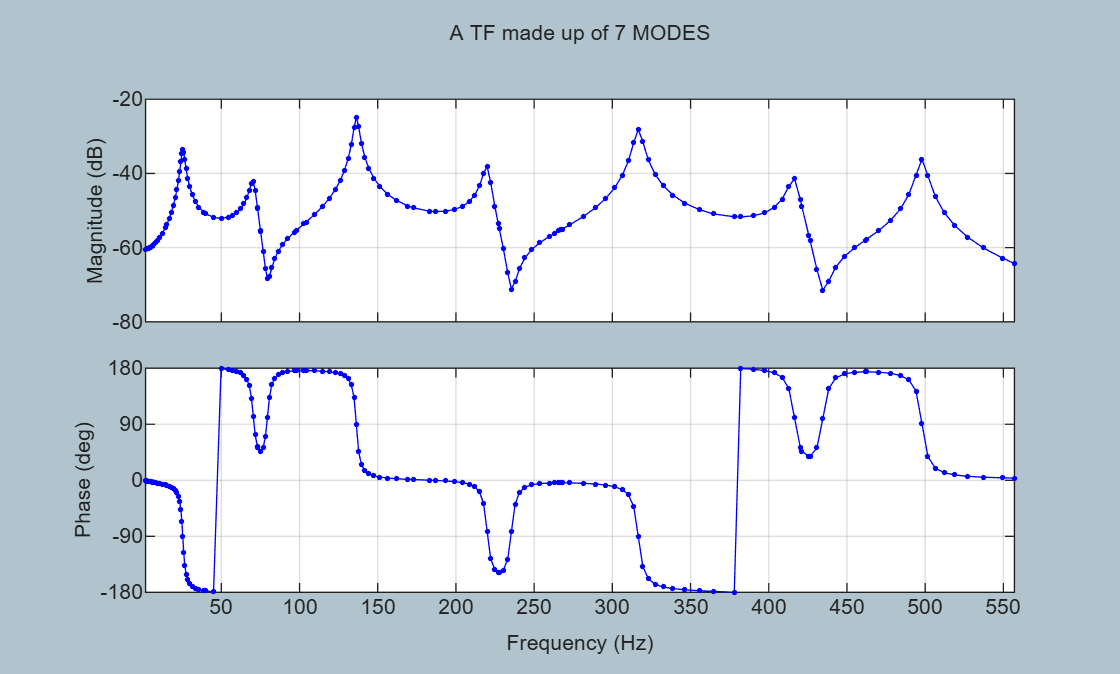

my_plot_opts = bodeoptions;
my_plot_opts.PhaseWrapping = "on";
my_plot_opts.FreqUnits = "Hz";
my_plot_opts.FreqScale = "linear";

figure;  
    bodeplot(THE_tf,'-b.', {10, 3500},my_plot_opts); grid on
        title("A TF made up of 7 MODES")

        axis tight

Let's plot the contributions of each:

- ZERO system(conjugate pairs and reals) and 

- POLE system(conjugate pairs)

tmp_imag = imag(z);
tmp_ind  = tmp_imag >= 0;  
list_zeros_pos_imag =  z(tmp_ind);

tmp_imag = imag(p);
tmp_ind  = tmp_imag >= 0;  
list_poles_pos_imag =  p(tmp_ind);

NUM_COLORS = length(list_zeros_pos_imag) + length(list_poles_pos_imag);
my_COLORS  = jet(NUM_COLORS);
w_list     = [10:0.1:3500]; 

db_mag_mat = zeros( length(w_list),  length(NUM_COLORS) );

#### Plot the contributions of the ZERO conjugate pairs AND real zeros

figure;
count=0;
for kk=1:length(list_zeros_pos_imag)
    count = count + 1;
    THE_ZERO = list_zeros_pos_imag(kk);
    if(imag(THE_ZERO)==0)
        tmp_sys = zpk(THE_ZERO,[],1);
        fprintf("\n .... REAL zero = %f",THE_ZERO);
        Line_spec = "--";
    else
       tmp_sys = zpk([THE_ZERO, conj(THE_ZERO)],[],1); 
       Line_spec = ".-";
    end

    if(1==kk)
        tmp_sys = tmp_sys * k;
    end

    [mag,~,~] = bode(tmp_sys, w_list);

    db_mag_mat(:,count) = 20*log10(mag(:));

    plot(w_list(:)/(2*pi), db_mag_mat(:,count), Line_spec, "Color",my_COLORS(count,:), "LineWidth",5)
    hold on
end


 .... REAL zero = -164.725549
 .... REAL zero = 149.636760

#### Plot the contributions of the POLE conjugate pairs 

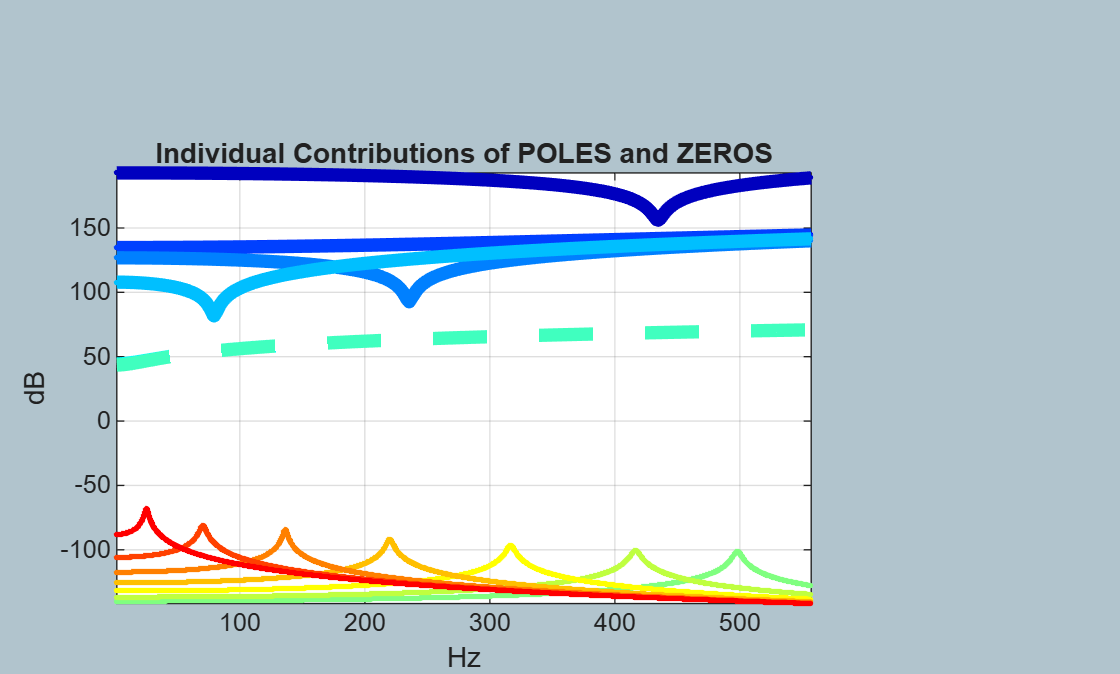

for kk=1:length(list_poles_pos_imag)
    count = count + 1;

    THE_POLE = list_poles_pos_imag(kk);

    the_sys = zpk([],[THE_POLE, conj(THE_POLE)],1);
    [mag,~,~] = bode(the_sys, w_list);

    db_mag_mat(:,count) = 20*log10(mag(:));

    plot(w_list(:)/(2*pi), db_mag_mat(:,count), ".-", "Color",my_COLORS(count,:), "LineWidth",1)
    hold on
end

grid on
xlabel("Hz");
ylabel("dB")
axis tight
title("Individual Contributions of POLES and ZEROS")

#### And on a LOGARITHMIC axis we can just ADD these up ... and should get the original FRF plot

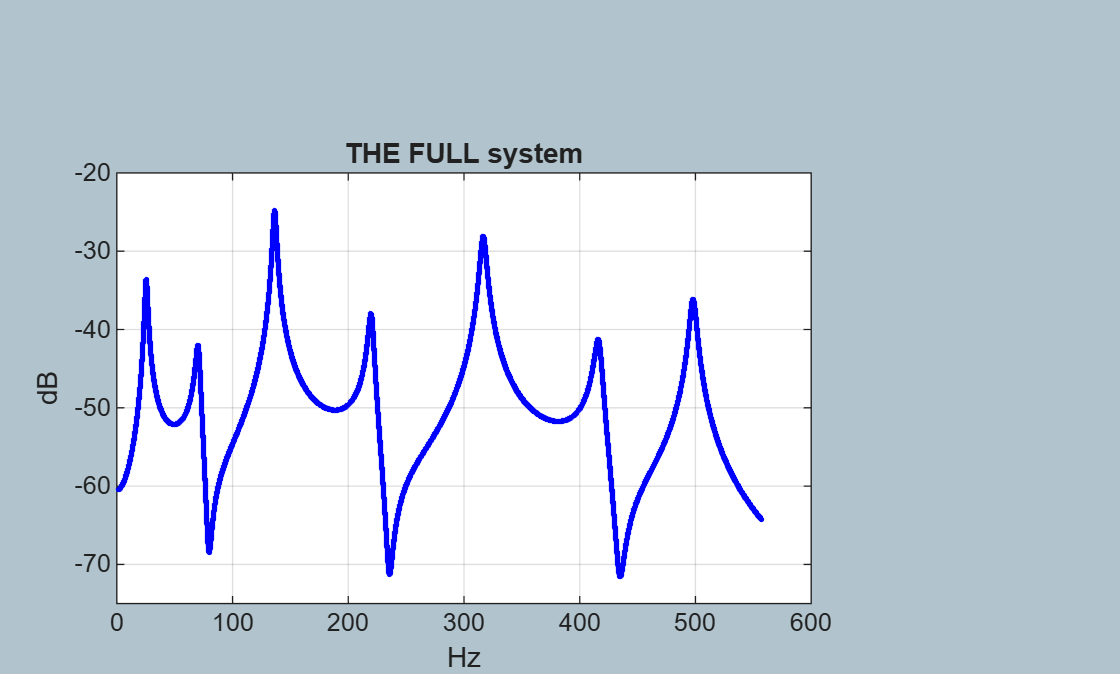

tmp_H = sum(db_mag_mat, 2);

figure;
   plot(w_list(:)/(2*pi), tmp_H, ".b-" );
        grid on
        xlabel("Hz");
        ylabel("dB")
        %axis tight
        ylim([-75, -20])
        xlim([0, 600])
        title("THE FULL system")